# Integration

This example shows how to compute definite integrals using Symbolic Math Toolbox™.

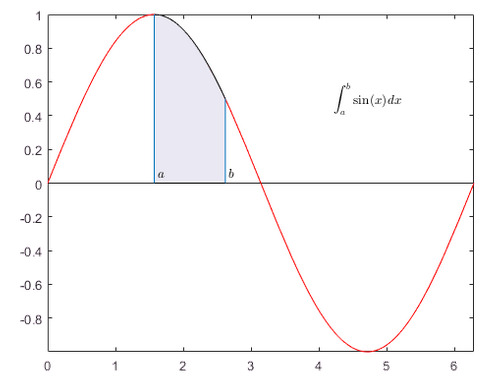

## Definite Integral

Show that the definite integral $\int\limits_{a}^{b}f(x)dx$ for $f(x)=sin(x)$ on $[\frac{\pi}{2},\frac{3\pi}{2}]$ is 0.

syms x
int(sin(x),pi/2,3*pi/2)

## Definite Integrals in Maxima and Minima

To maximize $F(a)=\int_{-a}^{a}\sin(ax)\sin(x/a)\,dx$ for $a \geq 0$, first, define the symbolic variables and assume that $a\geq 0$:

syms a x
assume(a >= 0);

Then, define the function to maximize:

F = int(sin(a*x)*sin(x/a),x,-a,a)

Note the special case here for $a=1$. To make computations easier, use `assumeAlso` to ignore this possibility (and later check that $a=1$ is not the maximum):

assumeAlso(a ~= 1);
F = int(sin(a*x)*sin(x/a),x,-a,a)

Create a plot of $F$ to check its shape:

fplot(F,[0 10])

Use `diff` to find the derivative of $F$ with respect to $a$:

Fa = diff(F,a)

The zeros of $Fa$ are the local extrema of $F$:

hold on
fplot(Fa,[0 10])
grid on

The maximum is between 1 and 2. Use `vpasolve` to find an approximation of the zero of $Fa$ in this interval:

a_max = vpasolve(Fa,a,[1,2])

Use `subs` to get the maximal value of the integral:

F_max = subs(F,a,a_max)

The result still contains exact numbers $\sin(1)$ and $\cos(1)$. Use `vpa` to replace these by numerical approximations:

vpa(F_max)

Check that the excluded case $a=1$ does not result in a larger value:

vpa(int(sin(x)*sin(x),x,-1,1))

## Multiple Integration

Numerical integration over higher dimensional areas has special functions:

integral2(@(x,y) x.^2-y.^2,0,1,0,1)

There are no such special functions for higher-dimensional symbolic integration. Use nested one-dimensional integrals instead:

syms x y
int(int(x^2-y^2,y,0,1),x,0,1)

## Line Integrals

Define a vector field `F` in 3D space:

syms x y z
F(x,y,z) = [x^2*y*z, x*y, 2*y*z];

Next, define a curve:

syms t
ux(t) = sin(t);
uy(t) = t^2-t;
uz(t) = t;

The line integral of `F` along the curve `u` is defined as $\int f\cdot du = \int f(ux(t),uy(t),uz(t))\cdot \frac{du}{dt}\,dt$, where the $\cdot$ on the right-hand-side denotes a scalar product. 

Use this definition to compute the line integral for $t$ from $[0,1]$

F_int = int(F(ux,uy,uz)*diff([ux;uy;uz],t),t,0,1)

Get a numerical approximation of this exact result:

vpa(F_int)

*Copyright 2010-2016 The MathWorks, Inc.*